**SIMULAZIONE DINAMICA DI UN AMMORTIZZATORE D'ATTERRAGGIO OLEOPNEUMATICO CON STROZZATURA DIFFERENZIALE**

clc
close all
clear all

**DATI**

Vs = 3;         % [m/s]             Velocità di caduta (sink speed)
M = 10000;      % [kg]              Massa applicata su ammortizzatore
g = 9.81;       % [m/sec^2]         Accelerazione gravitazionale
Ah = 6000e-6;   % [m^2]             Area premente lato olio
Cpn = 8e3;      % [N*sec/m]         Smorzamento equivalente pneumatico
Kpn = 5000e3;   % [N/m]             Rigidezza equivalente pneumatico
H0 = 0.75;      % [m]               Altezza iniziale colonna gas
Ag = 4800e-6;   % [m^2]             Area premente pistone flottante
Pg0 = 4e6;      % [Pa]              Pressione di precarica gas
n = 1.3;        % [adimensionale]   Esponente politropica equivalente
rho = 850;      % [kg/m^3]          Densità olio
Ks = 2;         % [adimensionale]  Coefficiente di perdita di carico orifizio
As0 = 70e-6;    % [m^2]             Area orifizio (corsa di compressione)
Cmax = 0.5;     % [m]               Corsa massima
Be = 800e6;     % [Pa]              Bulk modulus effettivo
F0 = 25000;     % [N]               Forza verticale iniziale
tau = 3;        % [sec]             Costante di tempo caratteristica della frenata
Qs0 = 0;

**PARAMETRI DI SIMULAZIONE**

dt = 5e-5;    
Tsim = 4;         

**DEFINIZIONE DI STATI**

x1(1) = 0;
x2(1) = Vs;
x3(1) = 0;
x4(1) = 0;
Pg(1) = Pg0;
Qs(1) = Qs0;
u(1)  = F0;
errimp_x1(1)=(0.5)*(dt^2)*(g-(F0/M));
errimp_x2(1)=(0.5)*(dt^2)*(((F0/tau)/M)-(Ah/M)*((Be*Vs)/Cmax));
errimp_x3(1)=(0.5)*(dt^2)*(((Be*Vs)/Cmax)*(Ah/Cpn));

**INTEGRAZIONE NUMERICA: metodo di Eulero**

for i=1:1+round(Tsim/dt)
    t(i)=(i-1)*dt;
    u(i)=F0*exp(-t(i)/tau);
    x1p(i)=x2(i);
    x2p(i)=g-(x4(i)*Ah)/M-u(i)/M;
    x3p(i)=(Ah*x4(i)-Kpn*x3(i))/Cpn;
    if x2(i)<x3p(i)
        As(i) = As0/3;
    else
        As(i)=As0;
    end
    if x4(i)<Pg0
        Pg(i)=Pg0;
        Qs(i)=0;
    else
        Pg(i)=Pg0*(((1-(Ah*(x1(i)-x3(i)))/(Ag*H0)))^(-n));
        Qs(i)=As(i)*sqrt((2*abs(x4(i)-Pg(i)))/(rho*Ks))*(sign(x4(i)-Pg(i)));
    end
    x4p(i)=Be*(Ah*(x2(i)-x3p(i))-Qs(i))/(Ah*(Cmax-(x1(i)-x3(i))));
    if t(i)<Tsim
        x1(i+1)=x1(i)+x1p(i)*dt;
        x2(i+1)=x2(i)+x2p(i)*dt;
        x3(i+1)=x3(i)+x3p(i)*dt;
        x4(i+1)=x4(i)+x4p(i)*dt;
    end

    errimp_x1(i)=(0.5)*(x2p(i))*(dt^2);
    errimp_x2(i)=(0.5)*(dt^2)*((F0/tau)*exp((-t(i))/tau))/M-(Ah/M)*(x4p(i));
    errimp_x3(i)=(0.5)*(dt^2)*((Ah/Cpn)*x4p(i)-(Kpn/Cpn)*x3p(i));
end

**GRAFICO DEL CARICO OLEODINAMICO, PNEUMATICO E TOTALE**

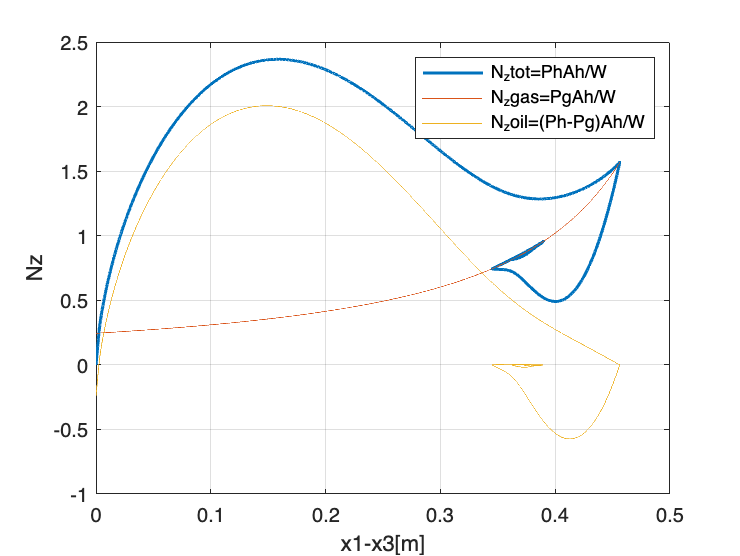

figure,
plot(x1-x3,x4*Ah/(M*g),'LineWidth',1.5)
hold on
plot(x1-x3,(Pg*Ah)/(M*g))
plot(x1-x3,(x4-Pg)*Ah/(M*g))
legend('N_ztot=PhAh/W','N_zgas=PgAh/W','N_zoil=(Ph-Pg)Ah/W'),...
    xlabel('x1-x3[m]'),...
    ylabel('Nz')
grid on

**GRAFICI DEGLI OUTPUT**

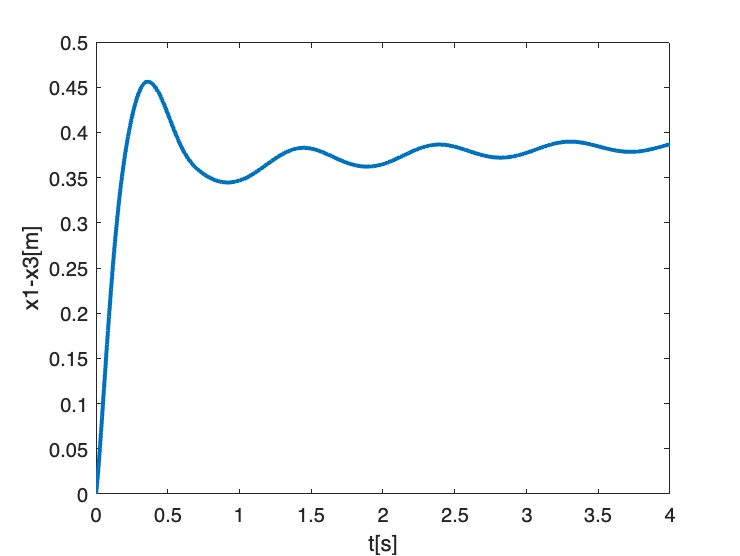

figure,
plot(t, x1-x3,'LineWidth',2)
xlabel('t[s]'),...
    ylabel('x1-x3[m]')

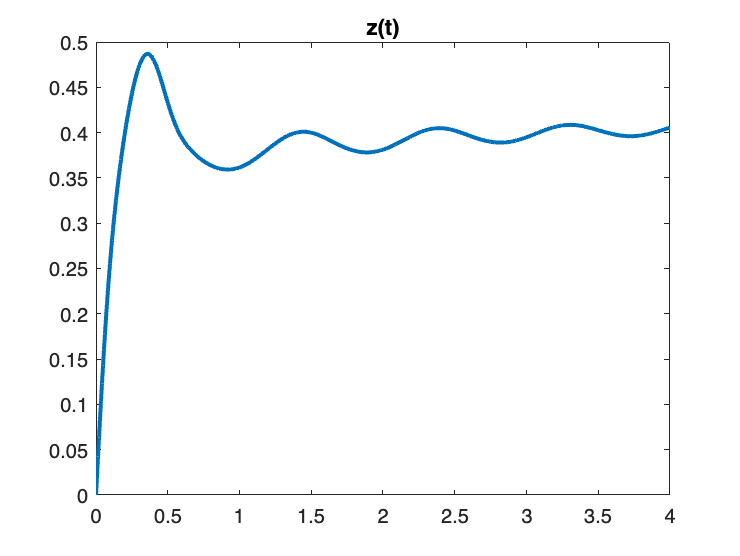


figure,
plot(t,x1,'LineWidth',2)
title('z(t)')

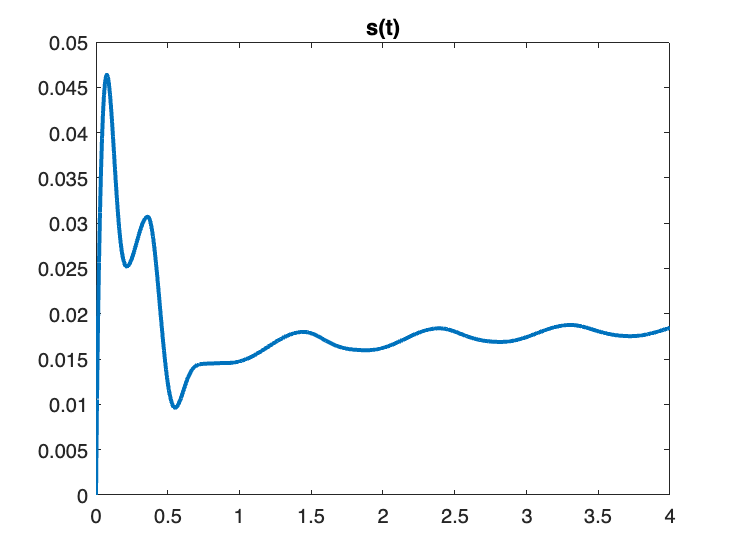


figure,
plot(t,x3,'LineWidth',2)
title('s(t)')

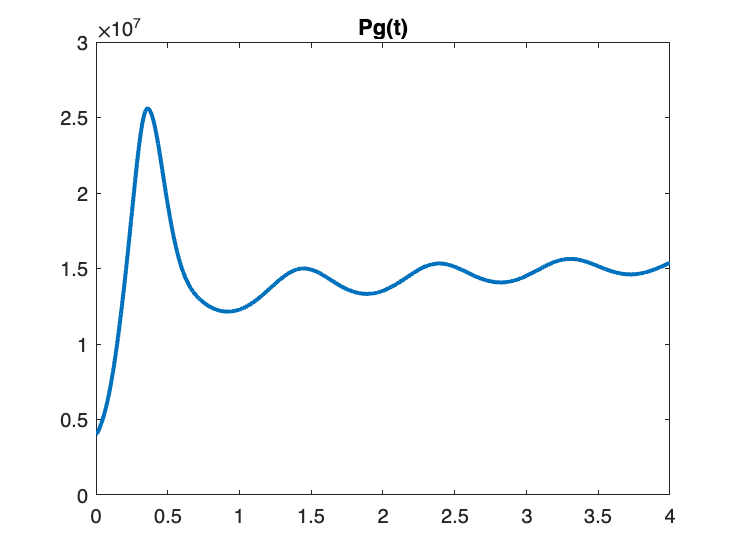


figure,
plot(t,Pg,'LineWidth',2)
title('Pg(t)')

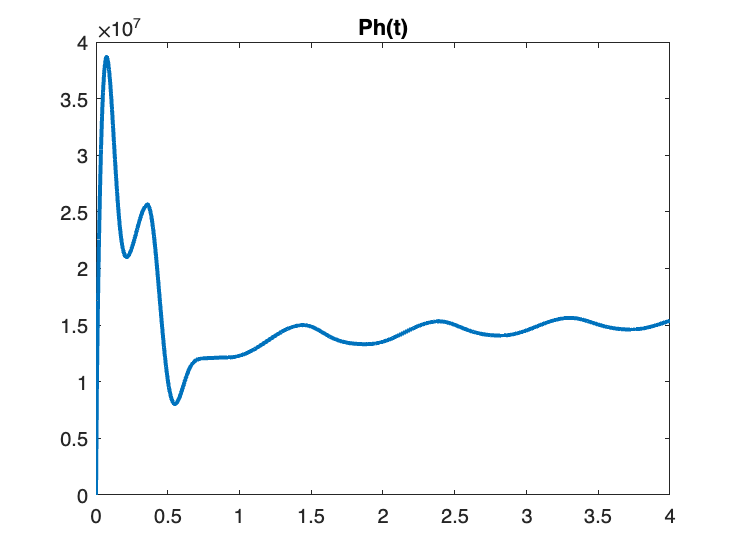


figure,
plot(t,x4,'LineWidth',2)
title('Ph(t)')

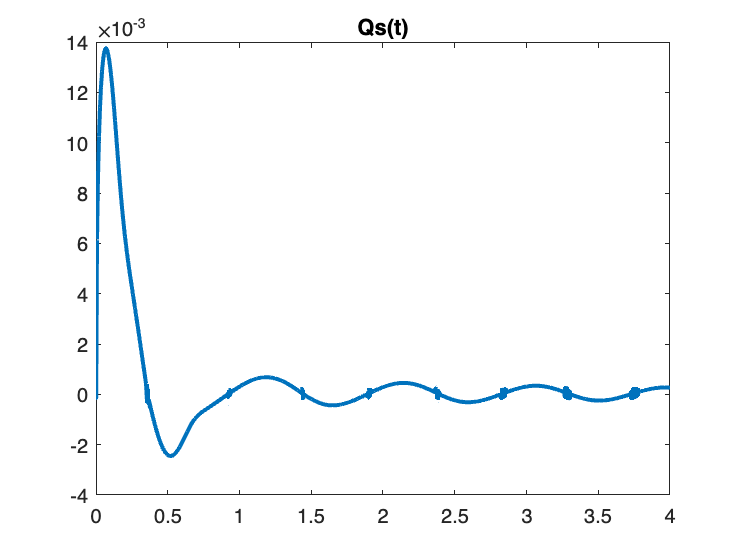


figure,
plot(t,Qs,'LineWidth',2)
title('Qs(t)')

## valutazione errori di implementazione

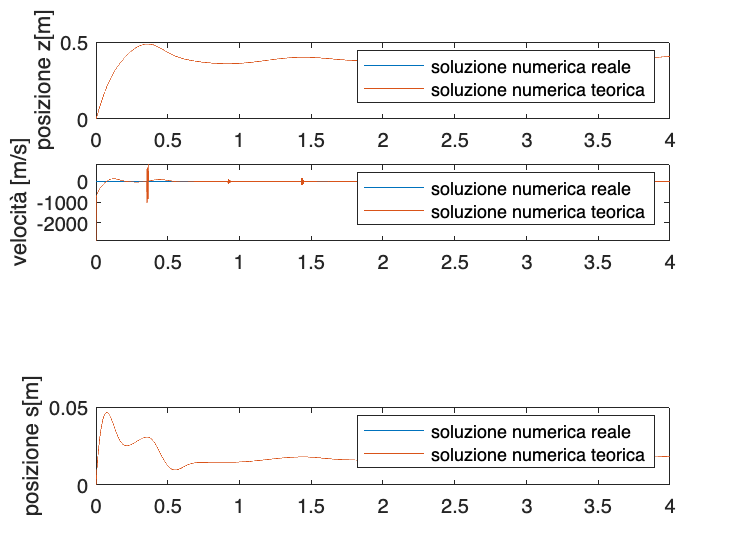

figure,
subplot(411),...
    plot(t,x1,t,errimp_x1+x1)
legend('soluzione numerica reale','soluzione numerica teorica')
ylabel('posizione z[m]')
subplot(412),...
    plot(t,x2,t,errimp_x2+x2)
legend('soluzione numerica reale','soluzione numerica teorica')
ylabel('velocità [m/s]')
subplot(414),...
    plot(t,x3,t,errimp_x3+x3)
legend('soluzione numerica reale','soluzione numerica teorica')
ylabel('posizione s[m]')